%% My image A
imgA = imread('\\Client\E$\Computer Vision\Nayan.jpg');
figure;
imgA = rgb2gray(imgA);

ftA = fft2(imgA);
phaseA = unwrap(angle(ftA));
mag = abs(fftshift(ftA));
outAM = mag .* exp(j*0);
outAP = 1 .* exp(j*phaseA);
outAP = ifft2(outAP);

%% Friend's image B
imgB = rgb2gray(imread('\\Client\E$\Computer Vision\baby.jpg'));


imgB = imadjust(imgB);
ftB = fft2(imgB);
phaseB = unwrap(angle(ftB));
mag = abs(fftshift(ftB));
outBM = mag .* exp(j*0);
outBP = 1 .* exp(j*phaseB);

subplot(2,3,1)
imshow(imgA)

%Displaying Magnitude only reconstruction of FT
subplot(2,3,2)
imshow(log(1+ifft2(outAM)),[],'InitialMagnification','fit')

%% Displaying Phase only reconstruction of FT
subplot(2,3,3)
imshow(log(1+outAP),[],'InitialMagnification','fit')

subplot(2,3,4)
imshow(imgB)
subplot(2,3,5)
%% Displaying Magnitude only reconstruction of FT
imshow(log(1+ifft2(outBM)),[],'InitialMagnification','fit')

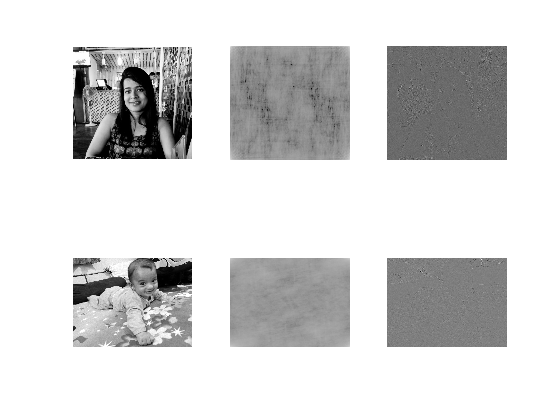

%% Displaying Phase only reconstruction of FT
subplot(2,3,6)
imshow(log(1+ifft2(outBP)),[],'InitialMagnification','fit')

## Part 2 (i)

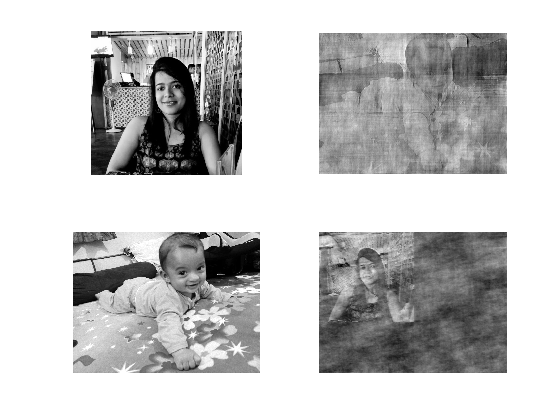

figure
imgB = imadjust(imgB);
[rA,cA] = size(imgA);
[rB,cB] = size(imgB);
r = max(rA,rB);
c = max(rB,cB);
ftA = fft2(imgA, r, c);
ftB = fft2(imgB, r,c);
rc1 = abs(ftA) .* exp(j*angle(ftB));
rc2 = abs(ftB) .* exp(j*angle(ftA));
subplot(2,2,1)
imshow(imgA)
subplot(2,2,2)
imshow(ifft2(rc1),[],'InitialMagnification','fit')
subplot(2,2,3)
imshow(imgB)
subplot(2,2,4)
imshow(ifft2(rc2),[],'InitialMagnification','fit')